theta_lat = deg2rad(19.8);
theta_lon = deg2rad(25.64);
lat_d = 1/6;
lon_d = 1/8;
d = 0.06;
r_lat = [-lat_d/2, -d/2; lat_d/2, d/2];

circle_1 = linspace(pi/2 + theta_lat, pi/2 - theta_lat, 30);
circle_2 = linspace(theta_lat - pi/2, -pi/2 - theta_lat, 30);
circle = linspace(0,2*pi, 100);

circle_x1 = d*cos(circle_1) + r_lat(1,1);
circle_y1 = d*sin(circle_1) - d/2;
circle_x2 = d*cos(circle_2) + r_lat(2,1);
circle_y2 = d*sin(circle_2) + d/2;
circle_x3 = d*cos(circle) + r_lat(1,1);
circle_y3 = d*sin(circle) - d/2;
circle_x4 = d*cos(circle) + r_lat(2,1);
circle_y4 = d*sin(circle) + d/2;
circle_x5 = d/2*cos(circle) + r_lat(1,1);
circle_y5 = d/2*sin(circle) - d/2;
circle_x6 = d/2*cos(circle) + r_lat(2,1);
circle_y6 = d/2*sin(circle) + d/2;
circle_x7 = d/2*cos(circle_1) + r_lat(1,1);
circle_y7 = d/2*sin(circle_1) - d/2;
circle_x8 = d/2*cos(circle_2) + r_lat(2,1);
circle_y8 = d/2*sin(circle_2) + d/2;
circle_x9 = d/2*3*cos(circle_1) + r_lat(1,1);
circle_y9 = d/2*3*sin(circle_1) - d/2;
circle_x10 = d/2*3*cos(circle_2) + r_lat(2,1);
circle_y10 = d/2*3*sin(circle_2) + d/2;

line_1 = [-lat_d, 0; circle_x1(1), circle_y1(1)];
line_2 = [circle_x1(end), circle_y1(end); circle_x2(end), circle_y2(end)];
line_3 = [circle_x2(1), circle_y2(1); lat_d, 0]

line_3 =     0.1037   -0.0265
    0.1667         0


abs((line_2(1,2)-line_2(2,2))/(line_2(1,1)-line_2(2,1)))

ans = 0.4198

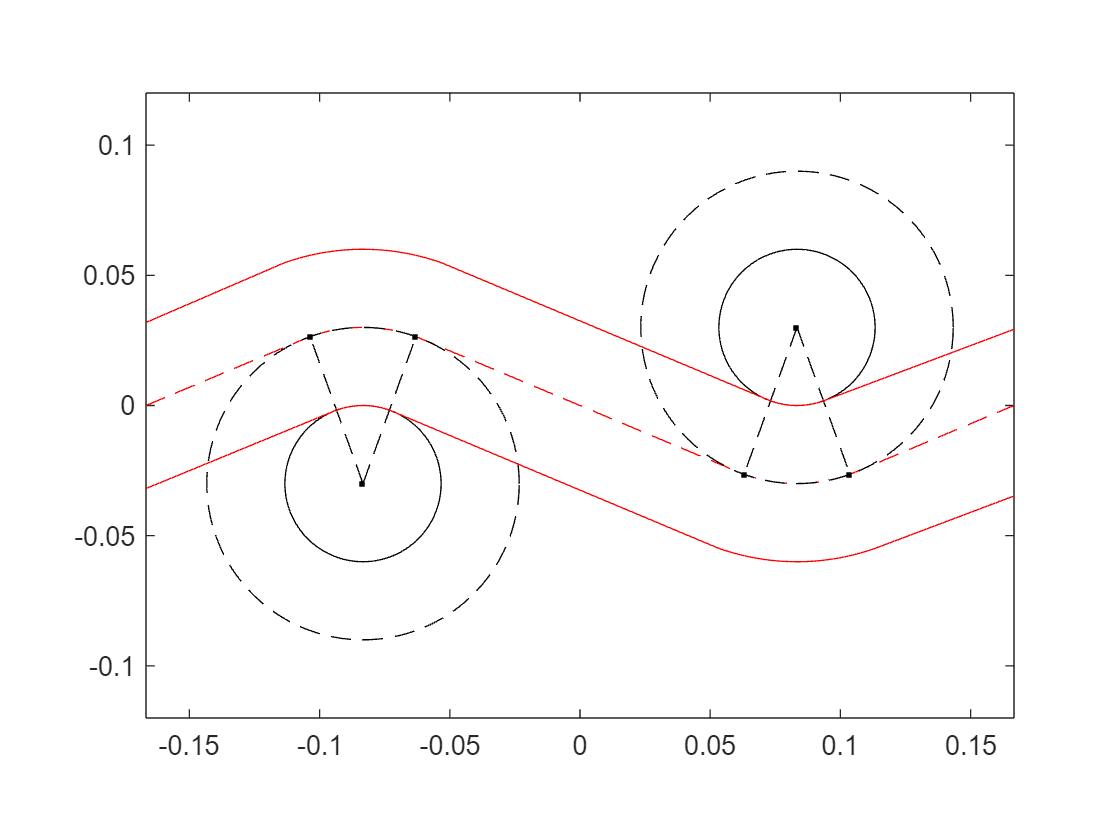

clf
plot(circle_x1, circle_y1, '--r', circle_x2, circle_y2, '--r');
axis equal;
xlim([-lat_d, lat_d])
ylim([-2*d, 2*d])
hold on;
plot(line_1(:,1), line_1(:,2), '--r')
plot(line_2(:,1), line_2(:,2), '--r')
plot(line_3(:,1), line_3(:,2), '--r')
hold on;
plot(circle_x3, circle_y3, '--k', circle_x4, circle_y4, '--k')
hold on;
plot(circle_x5, circle_y5, '-k', circle_x6, circle_y6, '-k')
hold on;
plot([r_lat(1,1), circle_x1(1)], [r_lat(1,2), circle_y1(1)], '--.k')
plot([r_lat(1,1), circle_x1(end)], [r_lat(1,2), circle_y1(end)], '--.k')
hold on;
plot([r_lat(2,1), circle_x2(1)], [r_lat(2,2), circle_y2(1)], '--.k')
plot([r_lat(2,1), circle_x2(end)], [r_lat(2,2), circle_y2(end)], '--.k')
hold on;
plot(circle_x7, circle_y7, '-r', circle_x8, circle_y8, '-r', circle_x9, circle_y9, '-r', circle_x10, circle_y10, '-r')
plot([-lat_d, circle_x9(1)], [d/2/cos(theta_lat), circle_y9(1)], '-r')
plot([-lat_d, circle_x7(1)], [-d/2/cos(theta_lat), circle_y7(1)], '-r')
plot([circle_x10(end), circle_x7(end)], [circle_y10(end), circle_y7(end)], '-r')
plot([circle_x8(end), circle_x9(end)], [circle_y8(end), circle_y9(end)], '-r')
plot([lat_d*2, circle_x8(1)], [d+d/2/cos(theta_lat), circle_y8(1)], '-r')
plot([lat_d*2, circle_x10(1)], [d-d/2/cos(theta_lat), circle_y10(1)], '-r')

x = linspace(0, 0.5, 100)

x =          0    0.0051    0.0101    0.0152    0.0202    0.0253    0.0303    0.0354    0.0404    0.0455    0.0505    0.0556    0.0606    0.0657    0.0707    0.0758    0.0808    0.0859    0.0909    0.0960    0.1010    0.1061    0.1111    0.1162    0.1212    0.1263    0.1313    0.1364    0.1414    0.1465    0.1515    0.1566    0.1616    0.1667    0.1717    0.1768    0.1818    0.1869    0.1919    0.1970    0.2020    0.2071    0.2121    0.2172    0.2222    0.2273    0.2323    0.2374    0.2424    0.2475


y = -tand(19.8)*(x-1/6) + d

y =     0.1200    0.1182    0.1164    0.1145    0.1127    0.1109    0.1091    0.1073    0.1055    0.1036    0.1018    0.1000    0.0982    0.0964    0.0945    0.0927    0.0909    0.0891    0.0873    0.0855    0.0836    0.0818    0.0800    0.0782    0.0764    0.0745    0.0727    0.0709    0.0691    0.0673    0.0655    0.0636    0.0618    0.0600    0.0582    0.0564    0.0545    0.0527    0.0509    0.0491    0.0473    0.0455    0.0436    0.0418    0.0400    0.0382    0.0364    0.0345    0.0327    0.0309


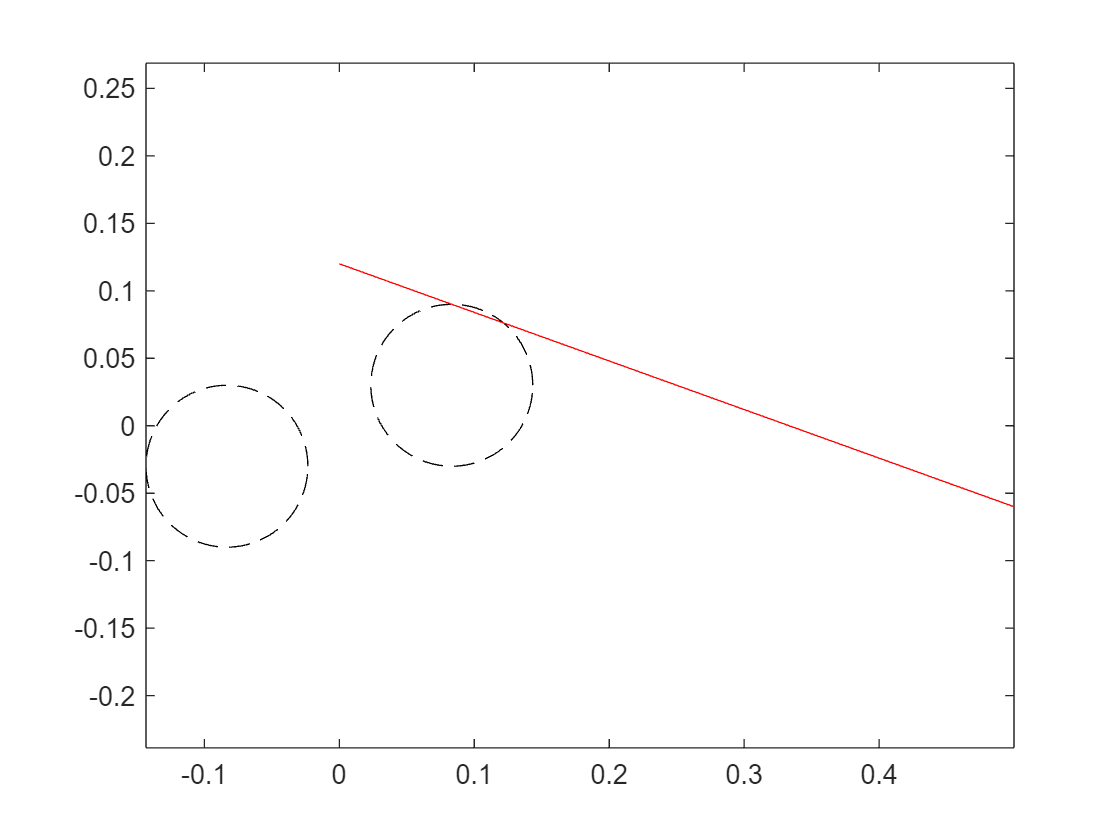


clf
plot(circle_x3, circle_y3, '--k', circle_x4, circle_y4, '--k')
hold on
plot(x, y, '-r')
axis equal;